## Q3 - part a | ARMAX

clc; clear;

%%

load q3_402123100.mat

u1_val = u2;
y1_val = y2;

u2_val = u1;
y2_val = y1;

### Guassian Input - PRBS Validation

%%
% Guassian Input **************************************************************
fprintf("*****************************************************************\n")

*****************************************************************


fprintf(">>> Guassian Input Identification Begins:------------------------------\n")

>>> Guassian Input Identification Begins:------------------------------


%%

Ts = 0.1; 
t = 0:Ts:length(u1)*Ts-Ts;
t_val = 0:Ts:length(u1_val)*Ts-Ts;
N = length(y1);
N_val = length(y1_val);

data_guassian = iddata(y1,u1,Ts);


%%

fprintf("====================Degree Extraction | RUN===========================\n")

====================Degree Extraction | RUN===========================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 0.75;

for degree=1:100
    na = degree;
    nb = degree;
    nc = degree;
    nk = 1;
    p = na+nb+nc;
    
    try
        sys = armax(data_guassian, [na nb nc nk]);
        armax_y_hat_guassian = lsim(sys, u1, t);
    catch
        break
    end

    [r2_armax, mse_armax] = rSQR(y1, armax_y_hat_guassian);

    error = y1 - armax_y_hat_guassian;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end

    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);
    
    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f | \n", degree, r2_armax, mse_armax, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_armax];
    MSEs = [MSEs; mse_armax];
    vars = [vars; variance];    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    
end

>>> Degree = 1 : R2=0.894175 | MSE=0.028480 | var=0.028501 | s_hat=116.653345 | 


-------------------------------------------------------------


>>> Degree = 2 : R2=0.941007 | MSE=0.015876 | var=0.015900 | s_hat=65.029299 | 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.941070 | MSE=0.015859 | var=0.015894 | s_hat=64.960181 | 


-------------------------------------------------------------


>>> Degree = 4 : R2=0.941097 | MSE=0.015852 | var=0.015899 | s_hat=64.929912 | 


-------------------------------------------------------------


>>> Degree = 5 : R2=0.941096 | MSE=0.015852 | var=0.015911 | s_hat=64.931427 | 


-------------------------------------------------------------


>>> Degree = 6 : R2=0.941174 | MSE=0.015831 | var=0.015901 | s_hat=64.845300 | 


-------------------------------------------------------------


>>> Degree = 7 : R2=0.941183 | MSE=0.015829 | var=0.015911 | s_hat=64.835294 | 


-------------------------------------------------------------


>>> Degree = 8 : R2=0.941202 | MSE=0.015824 | var=0.015917 | s_hat=64.814153 | 


-------------------------------------------------------------


>>> Degree = 9 : R2=0.941275 | MSE=0.015804 | var=0.015909 | s_hat=64.733556 | 


-------------------------------------------------------------


>>> Degree = 10 : R2=0.941202 | MSE=0.015824 | var=0.015941 | s_hat=64.814492 | 


-------------------------------------------------------------


>>> Degree = 11 : R2=0.941333 | MSE=0.015789 | var=0.015917 | s_hat=64.670187 | 


-------------------------------------------------------------


>>> Degree = 12 : R2=0.941324 | MSE=0.015791 | var=0.015931 | s_hat=64.679666 | 


-------------------------------------------------------------


>>> Degree = 13 : R2=0.941346 | MSE=0.015785 | var=0.015937 | s_hat=64.655535 | 


-------------------------------------------------------------


>>> Degree = 14 : R2=0.941371 | MSE=0.015778 | var=0.015942 | s_hat=64.628138 | 


-------------------------------------------------------------


>>> Degree = 15 : R2=0.941412 | MSE=0.015767 | var=0.015943 | s_hat=64.583097 | 


-------------------------------------------------------------


>>> Degree = 16 : R2=0.941381 | MSE=0.015776 | var=0.015963 | s_hat=64.617357 | 


-------------------------------------------------------------


>>> Degree = 17 : R2=0.941471 | MSE=0.015751 | var=0.015950 | s_hat=64.517949 | 


-------------------------------------------------------------


>>> Degree = 18 : R2=0.941598 | MSE=0.015717 | var=0.015927 | s_hat=64.378164 | 


-------------------------------------------------------------


>>> Degree = 19 : R2=0.941511 | MSE=0.015741 | var=0.015963 | s_hat=64.474060 | 


-------------------------------------------------------------


>>> Degree = 20 : R2=0.941534 | MSE=0.015734 | var=0.015968 | s_hat=64.448280 | 


-------------------------------------------------------------


>>> Degree = 21 : R2=0.941619 | MSE=0.015712 | var=0.015957 | s_hat=64.354998 | 


-------------------------------------------------------------


>>> Degree = 22 : R2=0.941581 | MSE=0.015722 | var=0.015979 | s_hat=64.396575 | 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.941585 | MSE=0.015721 | var=0.015990 | s_hat=64.391735 | 


-------------------------------------------------------------


>>> Degree = 24 : R2=0.941613 | MSE=0.015713 | var=0.015994 | s_hat=64.361582 | 


-------------------------------------------------------------


>>> Degree = 25 : R2=0.942027 | MSE=0.015602 | var=0.015893 | s_hat=63.904233 | 


-------------------------------------------------------------


>>> Degree = 26 : R2=0.941623 | MSE=0.015710 | var=0.016015 | s_hat=64.349939 | 


-------------------------------------------------------------


>>> Degree = 27 : R2=0.941812 | MSE=0.015660 | var=0.015975 | s_hat=64.141421 | 


-------------------------------------------------------------


>>> Degree = 28 : R2=0.941808 | MSE=0.015661 | var=0.015989 | s_hat=64.146323 | 


-------------------------------------------------------------


>>> Degree = 29 : R2=0.941926 | MSE=0.015629 | var=0.015968 | s_hat=64.016313 | 


-------------------------------------------------------------


>>> Degree = 30 : R2=0.941929 | MSE=0.015628 | var=0.015979 | s_hat=64.013332 | 


-------------------------------------------------------------


>>> Degree = 31 : R2=0.941910 | MSE=0.015633 | var=0.015996 | s_hat=64.033572 | 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.942119 | MSE=0.015577 | var=0.015951 | s_hat=63.803226 | 


-------------------------------------------------------------


>>> Degree = 33 : R2=0.941095 | MSE=0.015853 | var=0.016245 | s_hat=64.932675 | 


-------------------------------------------------------------


>>> Degree = 34 : R2=0.941991 | MSE=0.015612 | var=0.016010 | s_hat=63.944735 | 


-------------------------------------------------------------


>>> Degree = 35 : R2=0.942003 | MSE=0.015608 | var=0.016019 | s_hat=63.931209 | 


-------------------------------------------------------------


>>> Degree = 36 : R2=0.941928 | MSE=0.015628 | var=0.016052 | s_hat=64.013789 | 


-------------------------------------------------------------


>>> Degree = 37 : R2=0.942157 | MSE=0.015567 | var=0.016000 | s_hat=63.761865 | 


-------------------------------------------------------------


>>> Degree = 38 : R2=0.940982 | MSE=0.015883 | var=0.016338 | s_hat=65.056345 | 


-------------------------------------------------------------


>>> Degree = 39 : R2=0.941900 | MSE=0.015636 | var=0.016096 | s_hat=64.045086 | 


-------------------------------------------------------------


>>> Degree = 40 : R2=0.942097 | MSE=0.015583 | var=0.016053 | s_hat=63.828138 | 


-------------------------------------------------------------


>>> Degree = 41 : R2=0.942064 | MSE=0.015592 | var=0.016075 | s_hat=63.864181 | 


-------------------------------------------------------------


>>> Degree = 42 : R2=0.942074 | MSE=0.015589 | var=0.016084 | s_hat=63.852609 | 


-------------------------------------------------------------


>>> Degree = 43 : R2=0.942367 | MSE=0.015510 | var=0.016015 | s_hat=63.530182 | 


-------------------------------------------------------------


>>> Degree = 44 : R2=0.942295 | MSE=0.015530 | var=0.016047 | s_hat=63.609247 | 


-------------------------------------------------------------


>>> Degree = 45 : R2=0.942375 | MSE=0.015508 | var=0.016037 | s_hat=63.521087 | 


-------------------------------------------------------------


>>> Degree = 46 : R2=0.942169 | MSE=0.015564 | var=0.016106 | s_hat=63.748295 | 


-------------------------------------------------------------


>>> Degree = 47 : R2=0.942357 | MSE=0.015513 | var=0.016066 | s_hat=63.540543 | 


-------------------------------------------------------------


>>> Degree = 48 : R2=0.942316 | MSE=0.015524 | var=0.016090 | s_hat=63.586012 | 


-------------------------------------------------------------


>>> Degree = 49 : R2=0.942309 | MSE=0.015526 | var=0.016104 | s_hat=63.594123 | 


-------------------------------------------------------------


>>> Degree = 50 : R2=0.942035 | MSE=0.015600 | var=0.016193 | s_hat=63.895681 | 


-------------------------------------------------------------


>>> Degree = 51 : R2=0.939694 | MSE=0.016230 | var=0.016859 | s_hat=66.476132 | 


-------------------------------------------------------------


>>> Degree = 52 : R2=0.942389 | MSE=0.015504 | var=0.016118 | s_hat=63.506051 | 


-------------------------------------------------------------


>>> Degree = 53 : R2=0.942313 | MSE=0.015525 | var=0.016152 | s_hat=63.589656 | 


-------------------------------------------------------------


>>> Degree = 54 : R2=0.942590 | MSE=0.015450 | var=0.016086 | s_hat=63.284049 | 


-------------------------------------------------------------


>>> Degree = 55 : R2=0.942888 | MSE=0.015370 | var=0.016015 | s_hat=62.956097 | 


-------------------------------------------------------------


>>> Degree = 56 : R2=0.942409 | MSE=0.015499 | var=0.016162 | s_hat=63.484084 | 


-------------------------------------------------------------


>>> Degree = 57 : R2=0.942516 | MSE=0.015470 | var=0.016144 | s_hat=63.365279 | 


-------------------------------------------------------------


>>> Degree = 58 : R2=0.942830 | MSE=0.015386 | var=0.016068 | s_hat=63.019388 | 


-------------------------------------------------------------


>>> Degree = 59 : R2=0.942733 | MSE=0.015412 | var=0.016108 | s_hat=63.126481 | 


-------------------------------------------------------------


>>> Degree = 60 : R2=0.942718 | MSE=0.015416 | var=0.016124 | s_hat=63.142838 | 


-------------------------------------------------------------


>>> Degree = 61 : R2=0.942973 | MSE=0.015347 | var=0.016065 | s_hat=62.861478 | 


-------------------------------------------------------------


>>> Degree = 62 : R2=0.942562 | MSE=0.015458 | var=0.016193 | s_hat=63.315081 | 


-------------------------------------------------------------


>>> Degree = 63 : R2=0.942918 | MSE=0.015362 | var=0.016105 | s_hat=62.922800 | 


-------------------------------------------------------------


>>> Degree = 64 : R2=0.943112 | MSE=0.015310 | var=0.016063 | s_hat=62.708731 | 


-------------------------------------------------------------


>>> Degree = 65 : R2=0.943005 | MSE=0.015339 | var=0.016105 | s_hat=62.826962 | 


-------------------------------------------------------------


>>> Degree = 66 : R2=0.943020 | MSE=0.015334 | var=0.016113 | s_hat=62.809698 | 


-------------------------------------------------------------


>>> Degree = 67 : R2=0.942852 | MSE=0.015380 | var=0.016173 | s_hat=62.995737 | 


-------------------------------------------------------------


>>> Degree = 68 : R2=0.943131 | MSE=0.015305 | var=0.016107 | s_hat=62.688248 | 


-------------------------------------------------------------


>>> Degree = 69 : R2=0.942780 | MSE=0.015399 | var=0.016219 | s_hat=63.074734 | 


-------------------------------------------------------------


>>> Degree = 70 : R2=0.942838 | MSE=0.015383 | var=0.016215 | s_hat=63.010616 | 


-------------------------------------------------------------


>>> Degree = 71 : R2=0.943053 | MSE=0.015326 | var=0.016166 | s_hat=62.774326 | 


-------------------------------------------------------------


>>> Degree = 72 : R2=0.942663 | MSE=0.015430 | var=0.016290 | s_hat=63.203292 | 


-------------------------------------------------------------


>>> Degree = 73 : R2=0.942968 | MSE=0.015348 | var=0.016215 | s_hat=62.867328 | 


-------------------------------------------------------------


>>> Degree = 74 : R2=0.943023 | MSE=0.015334 | var=0.016212 | s_hat=62.806536 | 


-------------------------------------------------------------


>>> Degree = 75 : R2=0.943017 | MSE=0.015335 | var=0.016227 | s_hat=62.813507 | 


-------------------------------------------------------------


>>> Degree = 76 : R2=0.943142 | MSE=0.015302 | var=0.016204 | s_hat=62.675695 | 


-------------------------------------------------------------


>>> Degree = 77 : R2=0.942958 | MSE=0.015351 | var=0.016269 | s_hat=62.878139 | 


-------------------------------------------------------------


>>> Degree = 78 : R2=0.943002 | MSE=0.015339 | var=0.016269 | s_hat=62.830238 | 


-------------------------------------------------------------


>>> Degree = 79 : R2=0.943320 | MSE=0.015254 | var=0.016191 | s_hat=62.479499 | 


-------------------------------------------------------------


>>> Degree = 80 : R2=0.943215 | MSE=0.015282 | var=0.016233 | s_hat=62.595227 | 


-------------------------------------------------------------


>>> Degree = 81 : R2=0.942842 | MSE=0.015382 | var=0.016352 | s_hat=63.005901 | 


-------------------------------------------------------------


>>> Degree = 82 : R2=-50573612831962615853430603776.000000 | MSE=13610418867027374717846683648.000000 | var=14480071605024449471140855808.000000 | s_hat=55748275679344126844300016222208.000000 | 


-------------------------------------------------------------


>>> Degree = 83 : R2=0.942756 | MSE=0.015406 | var=0.016403 | s_hat=63.101642 | 


-------------------------------------------------------------


>>> Degree = 84 : R2=0.943538 | MSE=0.015195 | var=0.016191 | s_hat=62.238820 | 


-------------------------------------------------------------


>>> Degree = 85 : R2=0.943119 | MSE=0.015308 | var=0.016324 | s_hat=62.701124 | 


-------------------------------------------------------------


>>> Degree = 86 : R2=0.943250 | MSE=0.015272 | var=0.016299 | s_hat=62.556142 | 


-------------------------------------------------------------



fprintf("=================================================================\n")

%%
fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 84 


na = bestFitDegree;
nb = bestFitDegree;
nc = bestFitDegree;
p = na+nb+nc;

BestFitModel_guassian = armax(data_guassian, [na nb nc 1])

BestFitModel_guassian =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)                                                  
                                                                                                           
  A(z) = 1 + 0.1794 z^-1 - 0.1271 z^-2 + 0.2046 z^-3 + 0.214 z^-4 - 0.2439 z^-5 + 0.5541 z^-6              
          + 0.5669 z^-7 - 0.03662 z^-8 + 0.4561 z^-9 + 0.5168 z^-10 - 0.1479 z^-11 + 0.4463 z^-12          
          + 0.5741 z^-13 - 0.01891 z^-14 - 0.1412 z^-15 + 0.5684 z^-16 + 0.08544 z^-17 + 0.2419 z^-18      
          + 0.4736 z^-19 - 0.07487 z^-20 + 0.08958 z^-21 + 0.1805 z^-22 + 0.1611 z^-23 + 0.1673 z^-24      
          + 0.2311 z^-25 + 0.1152 z^-26 - 0.2218 z^-27 - 0.03184 z^-28 - 0.2695 z^-29 + 0.155 z^-30        
          + 0.2449 z^-31 - 0.1874 z^-32 - 0.1959 z^-33 - 0.04641 z^-34 - 0.1267 z^-35 - 0.3121 z^-36       
          + 0.176 z^-37 - 0.2605 z^-38 - 0.5203 z^-39 + 0.08833 z^-40 - 0.004627 z^-41 - 0.1073 z^-42      
    

BestFit_y_hat_guassian = lsim(BestFitModel_guassian, u1_val, t_val);
% [armax_BestFit_r2, armax_BestFit_mse] = rSQR(y_val, BestFit_y_hat);


%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 25 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 25 


na = minVarIndex;
nb = minVarIndex;
nc = minVarIndex;
p = na+nb+nc;

armax_VarModel_guassian = armax(data_guassian, [na nb nc nk])

armax_VarModel_guassian =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)                                                 
                                                                                                          
  A(z) = 1 - 0.6369 z^-1 - 0.1519 z^-2 - 0.4378 z^-3 - 0.4319 z^-4 + 0.2646 z^-5 + 0.2285 z^              
          -6 + 0.8206 z^-7 - 0.7309 z^-8 + 0.3031 z^-9 - 0.6609 z^-10 - 0.02517 z^-11 + 1.028 z^-12       
          - 0.2974 z^-13 + 0.5281 z^-14 - 0.7234 z^-15 - 0.3857 z^-16 - 0.2124 z^-17 + 0.1451 z^-18       
          + 0.3051 z^-19 - 0.1103 z^-20 + 0.591 z^-21 - 0.4849 z^-22 - 0.05937 z^-23 + 0.1512 z^-24       
                                                                                    - 0.003266 z^-25      
                                                                                                          
                                                                                                          
  B(z) = 0.

Var_y_hat_guassian = lsim(armax_VarModel_guassian, u1_val, t_val);
% [armax_Var_r2, armax_Var_mse] = rSQR(y_val, Var_y_hat);

fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=0.75) occurs in iteration 2 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 2 



na = minAICIndex;
nb = minAICIndex;
nc = minAICIndex;
p = na+nb+nc;

armax_AICModel_guassian = armax(data_guassian, [na nb nc nk])

armax_AICModel_guassian =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
  A(z) = 1 - 1.14 z^-1 + 0.4313 z^-2                     
                                                         
  B(z) = 0.395 z^-1 - 0.1828 z^-2                        
                                                         
  C(z) = 1 - 0.977 z^-1 + 0.3611 z^-2                    
                                                         
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nc=2   nk=1
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                   
Estimated using ARMAX on time domain data "data_guassian".
Fit to estimation data: 76.24% (prediction focus)         
FPE: 0.01524, MSE: 0.0152                                 


AIC_y_hat_guassian = lsim(armax_AICModel_guassian, u1_val, t_val);
% [armax_AIC_r2, armax_AIC_mse] = rSQR(y_val, AIC_y_hat);

fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.16 as


fprintf("    Degree = %d \n", winner)

    Degree = 2 



na = winner;
nb = winner;
nc = winner;
p = na+nb+nc;

armax_FTestModel_guassian = armax(data_guassian, [na nb nc nk])

armax_FTestModel_guassian =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
  A(z) = 1 - 1.14 z^-1 + 0.4313 z^-2                     
                                                         
  B(z) = 0.395 z^-1 - 0.1828 z^-2                        
                                                         
  C(z) = 1 - 0.977 z^-1 + 0.3611 z^-2                    
                                                         
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nc=2   nk=1
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                   
Estimated using ARMAX on time domain data "data_guassian".
Fit to estimation data: 76.24% (prediction focus)         
FPE: 0.01524, MSE: 0.0152                                 


FTest_y_hat_guassian = lsim(armax_FTestModel_guassian, u1_val, t_val);
% [armax_FTest_r2, armax_FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("=================================================================\n")

%%

[armax_BestFit_r2_guassian, armax_BestFit_mse_guassian] = rSQR(y1_val, BestFit_y_hat_guassian);
[armax_Var_r2_guassian, armax_Var_mse_guassian] = rSQR(y1_val, Var_y_hat_guassian);
[armax_AIC_r2_guassian, armax_AIC_mse_guassian] = rSQR(y1_val, AIC_y_hat_guassian);
[armax_FTest_r2_guassian, armax_FTest_mse_guassian] = rSQR(y1_val, FTest_y_hat_guassian);

fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_BestFit_r2_guassian, armax_BestFit_mse_guassian)

    R2 value : 0.9414   | MSE : 0.0156 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_Var_r2_guassian, armax_Var_mse_guassian)

    R2 value : 0.9426   | MSE : 0.0153 


% fprintf("---------------------------------------------------------------\n")
% fprintf(">>> Covariance Method:\n")
% fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_Cov_r2, armax_Cov_mse)
fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_AIC_r2_guassian, armax_AIC_mse_guassian)

    R2 value : 0.9430   | MSE : 0.0152 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_FTest_r2_guassian, armax_FTest_mse_guassian)

    R2 value : 0.9430   | MSE : 0.0152 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")

%%

armax_BestFitError_guassian = y1_val - BestFit_y_hat_guassian;
armax_VarError_guassian = y1_val - Var_y_hat_guassian;
armax_AICError_guassian = y1_val - AIC_y_hat_guassian;
armax_FTestError_guassian = y1_val - FTest_y_hat_guassian;

for k=0:N_val-1
    armax_BestFit_Ree_guassian(k+1,1) = AutoCorrelate(armax_BestFitError_guassian, k);
    armax_Var_Ree_guassian(k+1,1) = AutoCorrelate(armax_VarError_guassian, k);
    armax_AIC_Ree_guassian(k+1,1) = AutoCorrelate(armax_AICError_guassian, k);
    armax_FTest_Ree_guassian(k+1,1) = AutoCorrelate(armax_FTestError_guassian, k);
end

for k=0:N_val-1
    armax_BestFit_Rue_guassian(k+1,1) = CrossCorrelate(u1_val, armax_BestFitError_guassian, k);
    armax_Var_Rue_guassian(k+1,1) = CrossCorrelate(u1_val, armax_VarError_guassian, k);
    armax_AIC_Rue_guassian(k+1,1) = CrossCorrelate(u1_val, armax_AICError_guassian, k);
    armax_FTest_Rue_guassian(k+1,1) = CrossCorrelate(u1_val, armax_FTestError_guassian, k);
end



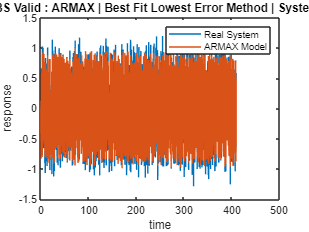

%%
figure(1)
plot(t_val,y1_val,t_val,BestFit_y_hat_guassian)
legend('Real System','ARMAX Model')
title(" Guassian Ident - PRBS Valid : ARMAX | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

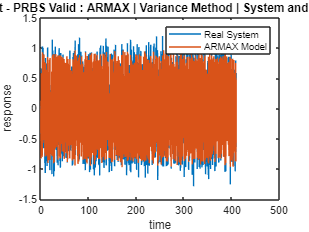


figure(2)
plot(t_val,y1_val,t_val,Var_y_hat_guassian)
legend('Real System','ARMAX Model')
title(" Guassian Ident - PRBS Valid : ARMAX | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

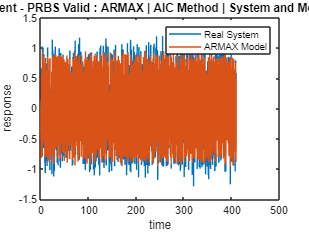


figure(3)
plot(t_val,y1_val,t_val,AIC_y_hat_guassian)
legend('Real System','ARMAX Model')
title(" Guassian Ident - PRBS Valid : ARMAX | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

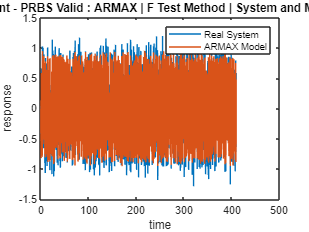


figure(4)
plot(t_val,y1_val,t_val,FTest_y_hat_guassian)
legend('Real System','ARMAX Model')
title(" Guassian Ident - PRBS Valid : ARMAX | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

%%

figure(5)
subplot(4,1,1)
plot(1:N_val-1,armax_BestFit_Ree_guassian(2:end), 1:N_val-1, mean(armax_BestFit_Ree_guassian(2:end))*ones(length(1:N_val-1)))
title(" Guassian Ident - PRBS Valid : ARMAX | Best Fit Lowest Errror Method | Ree_guassian(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_guassian(k)")

subplot(4,1,2)
plot(1:N_val-1,armax_Var_Ree_guassian(2:end), 1:N_val-1, mean(armax_Var_Ree_guassian(2:end))*ones(length(1:N_val-1)))
title(" Guassian Ident - PRBS Valid : ARMAX | Variance Method | Ree_guassian(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_guassian(k)")

subplot(4,1,3)
plot(1:N_val-1,armax_AIC_Ree_guassian(2:end), 1:N_val-1, mean(armax_AIC_Ree_guassian(2:end))*ones(length(1:N_val-1)))
title(" Guassian Ident - PRBS Valid : ARMAX | AIC Method | Ree_guassian(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_guassian(k)")

subplot(4,1,4)
plot(1:N_val-1,armax_FTest_Ree_guassian(2:end), 1:N_val-1, mean(armax_FTest_Ree_guassian(2:end))*ones(length(1:N_val-1)))
title(" Guassian Ident - PRBS Valid : ARMAX | F Test Method | Ree_guassian(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_guassian(k)")


%%

figure(6)
subplot(4,1,1)
plot(1:N_val-1,armax_BestFit_Rue_guassian(2:end), 1:N_val-1, mean(armax_BestFit_Rue_guassian(2:end))*ones(length(1:N_val-1)))
title(" Guassian Ident - PRBS Valid : ARMAX | Best Fit Lowest Errror Method | Rue_guassian(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_guassian(k)")

subplot(4,1,2)
plot(1:N_val-1,armax_Var_Rue_guassian(2:end), 1:N_val-1, mean(armax_Var_Rue_guassian(2:end))*ones(length(1:N_val-1)))
title(" Guassian Ident - PRBS Valid : ARMAX | Variance Method | Rue_guassian(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_guassian(k)")

subplot(4,1,3)
plot(1:N_val-1,armax_AIC_Rue_guassian(2:end), 1:N_val-1, mean(armax_AIC_Rue_guassian(2:end))*ones(length(1:N_val-1)))
title(" Guassian Ident - PRBS Valid : ARMAX | AIC Method | Rue_guassian(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_guassian(k)")

subplot(4,1,4)
plot(1:N_val-1,armax_FTest_Rue_guassian(2:end), 1:N_val-1, mean(armax_FTest_Rue_guassian(2:end))*ones(length(1:N_val-1)))
title(" Guassian Ident - PRBS Valid : ARMAX | F Test Method | Rue_guassian(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_guassian(k)")


###  PRBS Input - Guassian Validation

%%
% PRBS Input **************************************************************
fprintf("*****************************************************************\n")

*****************************************************************


fprintf(">>> PRBS Input Identification Begins:------------------------------\n")

>>> PRBS Input Identification Begins:------------------------------


%%

t = 0:Ts:length(u2)*Ts-Ts;
t_val = 0:Ts:length(u2_val)*Ts-Ts;
N = length(y2);
N_val = length(y2_val);

data_prbs = iddata(y2,u2,Ts);



%%


fprintf("====================Degree Extraction | RUN===========================\n")

====================Degree Extraction | RUN===========================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 0.75;

for degree=1:100
    na = degree;
    nb = degree;
    nc = degree;
    nk = 1;
    p = na+nb+nc;
    
    try
        sys = armax(data_prbs, [na nb nc nk]);
        armax_y_hat_prbs = lsim(sys, u2, t);
    catch
        break
    end

    [r2_armax, mse_armax] = rSQR(y2, armax_y_hat_prbs);

    error = y2 - armax_y_hat_prbs;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end

    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);
    
    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f | \n", degree, r2_armax, mse_armax, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_armax];
    MSEs = [MSEs; mse_armax];
    vars = [vars; variance];    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    
end

>>> Degree = 1 : R2=0.896281 | MSE=0.027642 | var=0.027662 | s_hat=113.220916 | 


-------------------------------------------------------------


>>> Degree = 2 : R2=0.943231 | MSE=0.015129 | var=0.015151 | s_hat=61.969490 | 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.943233 | MSE=0.015129 | var=0.015162 | s_hat=61.968240 | 


-------------------------------------------------------------


>>> Degree = 4 : R2=0.943306 | MSE=0.015109 | var=0.015154 | s_hat=61.888331 | 


-------------------------------------------------------------


>>> Degree = 5 : R2=0.943425 | MSE=0.015078 | var=0.015133 | s_hat=61.758329 | 


-------------------------------------------------------------


>>> Degree = 6 : R2=0.943380 | MSE=0.015090 | var=0.015156 | s_hat=61.807142 | 


-------------------------------------------------------------


>>> Degree = 7 : R2=0.943385 | MSE=0.015088 | var=0.015166 | s_hat=61.802020 | 


-------------------------------------------------------------


>>> Degree = 8 : R2=0.943466 | MSE=0.015067 | var=0.015155 | s_hat=61.712944 | 


-------------------------------------------------------------


>>> Degree = 9 : R2=0.943615 | MSE=0.015027 | var=0.015127 | s_hat=61.550890 | 


-------------------------------------------------------------


>>> Degree = 10 : R2=0.943589 | MSE=0.015034 | var=0.015145 | s_hat=61.579227 | 


-------------------------------------------------------------


>>> Degree = 11 : R2=0.943662 | MSE=0.015015 | var=0.015137 | s_hat=61.499999 | 


-------------------------------------------------------------


>>> Degree = 12 : R2=0.943600 | MSE=0.015031 | var=0.015164 | s_hat=61.566932 | 


-------------------------------------------------------------


>>> Degree = 13 : R2=0.943733 | MSE=0.014996 | var=0.015140 | s_hat=61.422221 | 


-------------------------------------------------------------


>>> Degree = 14 : R2=0.943865 | MSE=0.014961 | var=0.015116 | s_hat=61.278385 | 


-------------------------------------------------------------


>>> Degree = 15 : R2=0.943755 | MSE=0.014990 | var=0.015156 | s_hat=61.398141 | 


-------------------------------------------------------------


>>> Degree = 16 : R2=0.943753 | MSE=0.014990 | var=0.015168 | s_hat=61.400538 | 


-------------------------------------------------------------


>>> Degree = 17 : R2=0.943876 | MSE=0.014958 | var=0.015146 | s_hat=61.266211 | 


-------------------------------------------------------------


>>> Degree = 18 : R2=0.943980 | MSE=0.014930 | var=0.015129 | s_hat=61.152503 | 


-------------------------------------------------------------


>>> Degree = 19 : R2=0.943829 | MSE=0.014970 | var=0.015181 | s_hat=61.317619 | 


-------------------------------------------------------------


>>> Degree = 20 : R2=0.943896 | MSE=0.014952 | var=0.015174 | s_hat=61.243710 | 


-------------------------------------------------------------


>>> Degree = 21 : R2=0.943774 | MSE=0.014985 | var=0.015219 | s_hat=61.377390 | 


-------------------------------------------------------------


>>> Degree = 22 : R2=0.943881 | MSE=0.014956 | var=0.015201 | s_hat=61.260650 | 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.944150 | MSE=0.014885 | var=0.015140 | s_hat=60.967056 | 


-------------------------------------------------------------


>>> Degree = 24 : R2=0.943867 | MSE=0.014960 | var=0.015228 | s_hat=61.276071 | 


-------------------------------------------------------------


>>> Degree = 25 : R2=0.944087 | MSE=0.014901 | var=0.015179 | s_hat=61.035899 | 


-------------------------------------------------------------


>>> Degree = 26 : R2=0.943802 | MSE=0.014977 | var=0.015268 | s_hat=61.346962 | 


-------------------------------------------------------------


>>> Degree = 27 : R2=0.944264 | MSE=0.014854 | var=0.015154 | s_hat=60.842730 | 


-------------------------------------------------------------


>>> Degree = 28 : R2=0.944122 | MSE=0.014892 | var=0.015204 | s_hat=60.997871 | 


-------------------------------------------------------------


>>> Degree = 29 : R2=0.943953 | MSE=0.014937 | var=0.015261 | s_hat=61.182139 | 


-------------------------------------------------------------


>>> Degree = 30 : R2=0.944176 | MSE=0.014877 | var=0.015212 | s_hat=60.938036 | 


-------------------------------------------------------------


>>> Degree = 31 : R2=0.944274 | MSE=0.014851 | var=0.015196 | s_hat=60.831441 | 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.944224 | MSE=0.014865 | var=0.015222 | s_hat=60.886215 | 


-------------------------------------------------------------


>>> Degree = 33 : R2=0.944049 | MSE=0.014911 | var=0.015281 | s_hat=61.076654 | 


-------------------------------------------------------------


>>> Degree = 34 : R2=0.944353 | MSE=0.014830 | var=0.015209 | s_hat=60.745488 | 


-------------------------------------------------------------


>>> Degree = 35 : R2=0.944246 | MSE=0.014859 | var=0.015250 | s_hat=60.861959 | 


-------------------------------------------------------------


>>> Degree = 36 : R2=0.943855 | MSE=0.014963 | var=0.015368 | s_hat=61.289197 | 


-------------------------------------------------------------


>>> Degree = 37 : R2=0.944155 | MSE=0.014883 | var=0.015298 | s_hat=60.960822 | 


-------------------------------------------------------------


>>> Degree = 38 : R2=0.944574 | MSE=0.014771 | var=0.015194 | s_hat=60.503544 | 


-------------------------------------------------------------


>>> Degree = 39 : R2=0.944561 | MSE=0.014775 | var=0.015209 | s_hat=60.517705 | 


-------------------------------------------------------------


>>> Degree = 40 : R2=0.944569 | MSE=0.014773 | var=0.015219 | s_hat=60.509045 | 


-------------------------------------------------------------


>>> Degree = 41 : R2=0.944551 | MSE=0.014778 | var=0.015235 | s_hat=60.529287 | 


-------------------------------------------------------------


>>> Degree = 42 : R2=0.944334 | MSE=0.014835 | var=0.015306 | s_hat=60.765534 | 


-------------------------------------------------------------


>>> Degree = 43 : R2=0.944609 | MSE=0.014762 | var=0.015242 | s_hat=60.466012 | 


-------------------------------------------------------------


>>> Degree = 44 : R2=0.944410 | MSE=0.014815 | var=0.015308 | s_hat=60.682537 | 


-------------------------------------------------------------


>>> Degree = 45 : R2=0.944759 | MSE=0.014722 | var=0.015224 | s_hat=60.301823 | 


-------------------------------------------------------------


>>> Degree = 46 : R2=0.944628 | MSE=0.014757 | var=0.015272 | s_hat=60.444840 | 


-------------------------------------------------------------


>>> Degree = 47 : R2=0.944682 | MSE=0.014743 | var=0.015268 | s_hat=60.385996 | 


-------------------------------------------------------------


>>> Degree = 48 : R2=0.942543 | MSE=0.015313 | var=0.015871 | s_hat=62.720831 | 


-------------------------------------------------------------


>>> Degree = 49 : R2=0.944680 | MSE=0.014743 | var=0.015292 | s_hat=60.387812 | 


-------------------------------------------------------------


>>> Degree = 50 : R2=0.944664 | MSE=0.014748 | var=0.015308 | s_hat=60.406269 | 


-------------------------------------------------------------


>>> Degree = 51 : R2=0.944937 | MSE=0.014675 | var=0.015244 | s_hat=60.107804 | 


-------------------------------------------------------------


>>> Degree = 52 : R2=0.944659 | MSE=0.014749 | var=0.015333 | s_hat=60.410868 | 


-------------------------------------------------------------


>>> Degree = 53 : R2=0.939271 | MSE=0.016185 | var=0.016838 | s_hat=66.292438 | 


-------------------------------------------------------------


>>> Degree = 54 : R2=0.944584 | MSE=0.014769 | var=0.015377 | s_hat=60.493508 | 


-------------------------------------------------------------


>>> Degree = 55 : R2=-74393247604066617004524568576.000000 | MSE=19826403315487381845853601792.000000 | var=20658597807233859187772489728.000000 | s_hat=81208947980236298026217843458048.000000 | 


-------------------------------------------------------------


>>> Degree = 56 : R2=0.944717 | MSE=0.014733 | var=0.015363 | s_hat=60.347487 | 


-------------------------------------------------------------


>>> Degree = 57 : R2=0.944563 | MSE=0.014774 | var=0.015418 | s_hat=60.515929 | 


-------------------------------------------------------------


>>> Degree = 58 : R2=0.944852 | MSE=0.014697 | var=0.015349 | s_hat=60.200303 | 


-------------------------------------------------------------


>>> Degree = 59 : R2=0.944756 | MSE=0.014723 | var=0.015388 | s_hat=60.305245 | 


-------------------------------------------------------------


>>> Degree = 60 : R2=0.944742 | MSE=0.014727 | var=0.015404 | s_hat=60.320748 | 


-------------------------------------------------------------


>>> Degree = 61 : R2=0.944915 | MSE=0.014681 | var=0.015367 | s_hat=60.131846 | 


-------------------------------------------------------------


>>> Degree = 62 : R2=0.944898 | MSE=0.014685 | var=0.015384 | s_hat=60.149898 | 


-------------------------------------------------------------


>>> Degree = 63 : R2=0.944885 | MSE=0.014689 | var=0.015399 | s_hat=60.164397 | 


-------------------------------------------------------------


>>> Degree = 64 : R2=0.945138 | MSE=0.014621 | var=0.015340 | s_hat=59.888268 | 


-------------------------------------------------------------


>>> Degree = 65 : R2=0.945336 | MSE=0.014568 | var=0.015297 | s_hat=59.671768 | 


-------------------------------------------------------------


>>> Degree = 66 : R2=0.945051 | MSE=0.014644 | var=0.015388 | s_hat=59.983540 | 


-------------------------------------------------------------


>>> Degree = 67 : R2=-2746033392441135182203187402614249446331859181641917731114137133234418316242110343939341693435981555516643437707264.000000 | MSE=731840150951520992680279763780803027484848881564519865419322550339012697989672240287639245581870145366926028701696.000000 | var=769606484800367265766123082606652034246276195307867923513975485372103812143363457113670660900293470641847288201216.000000 | s_hat=2997617258297430545954611456897221839938511160999342899168919474850979735962972737166138144943576460642302331463925760.000000 | 


-------------------------------------------------------------


>>> Degree = 68 : R2=0.944629 | MSE=0.014757 | var=0.015530 | s_hat=60.443443 | 


-------------------------------------------------------------


>>> Degree = 69 : R2=0.944933 | MSE=0.014676 | var=0.015457 | s_hat=60.111837 | 


-------------------------------------------------------------


>>> Degree = 70 : R2=0.944780 | MSE=0.014717 | var=0.015512 | s_hat=60.279145 | 


-------------------------------------------------------------


>>> Degree = 71 : R2=0.944794 | MSE=0.014713 | var=0.015520 | s_hat=60.263770 | 


-------------------------------------------------------------


>>> Degree = 72 : R2=0.944528 | MSE=0.014784 | var=0.015607 | s_hat=60.554210 | 


-------------------------------------------------------------


>>> Degree = 73 : R2=-1569606.064068 | MSE=418313.001533 | var=441942.237369 | s_hat=1713410054.279447 | 


-------------------------------------------------------------


>>> Degree = 74 : R2=0.944803 | MSE=0.014711 | var=0.015554 | s_hat=60.254448 | 


-------------------------------------------------------------


>>> Degree = 75 : R2=0.945318 | MSE=0.014573 | var=0.015420 | s_hat=59.692101 | 


-------------------------------------------------------------


>>> Degree = 76 : R2=0.945103 | MSE=0.014630 | var=0.015493 | s_hat=59.925969 | 


-------------------------------------------------------------


>>> Degree = 77 : R2=0.929768 | MSE=0.018717 | var=0.019836 | s_hat=76.666505 | 


-------------------------------------------------------------


>>> Degree = 78 : R2=0.944743 | MSE=0.014726 | var=0.015619 | s_hat=60.319339 | 


-------------------------------------------------------------


>>> Degree = 79 : R2=0.945002 | MSE=0.014657 | var=0.015558 | s_hat=60.036526 | 


-------------------------------------------------------------


>>> Degree = 80 : R2=0.945228 | MSE=0.014597 | var=0.015506 | s_hat=59.790048 | 


-------------------------------------------------------------


>>> Degree = 81 : R2=0.945057 | MSE=0.014643 | var=0.015566 | s_hat=59.977124 | 


-------------------------------------------------------------


>>> Degree = 82 : R2=0.945228 | MSE=0.014597 | var=0.015530 | s_hat=59.790315 | 


-------------------------------------------------------------


>>> Degree = 83 : R2=-3.424753 | MSE=1.179232 | var=1.255559 | s_hat=4830.136103 | 


-------------------------------------------------------------


>>> Degree = 84 : R2=0.945126 | MSE=0.014624 | var=0.015583 | s_hat=59.901699 | 


-------------------------------------------------------------


>>> Degree = 85 : R2=0.945104 | MSE=0.014630 | var=0.015602 | s_hat=59.925522 | 


-------------------------------------------------------------


>>> Degree = 86 : R2=0.945154 | MSE=0.014617 | var=0.015599 | s_hat=59.870709 | 


-------------------------------------------------------------


>>> Degree = 87 : R2=0.944824 | MSE=0.014705 | var=0.015706 | s_hat=60.230912 | 


-------------------------------------------------------------


>>> Degree = 88 : R2=0.945019 | MSE=0.014653 | var=0.015662 | s_hat=60.018187 | 


-------------------------------------------------------------


>>> Degree = 89 : R2=0.944806 | MSE=0.014710 | var=0.015735 | s_hat=60.250266 | 


-------------------------------------------------------------


>>> Degree = 90 : R2=-57986043337651983210250240.000000 | MSE=15453750426386463415336960.000000 | var=16544318281881583106392064.000000 | s_hat=63298561746478936557034143744.000000 | 


-------------------------------------------------------------


>>> Degree = 91 : R2=0.945197 | MSE=0.014605 | var=0.015648 | s_hat=59.824038 | 


-------------------------------------------------------------


>>> Degree = 92 : R2=0.944911 | MSE=0.014682 | var=0.015742 | s_hat=60.135847 | 


-------------------------------------------------------------



fprintf("=================================================================\n")

%%


fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 65 


na = bestFitDegree;
nb = bestFitDegree;
nc = bestFitDegree;
p = na+nb+nc;

BestFitModel_prbs = armax(data_prbs, [na nb nc 1])

BestFitModel_prbs =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)                                               
                                                                                                        
  A(z) = 1 - 2.411 z^-1 + 2.765 z^-2 - 2.004 z^-3 + 1.134 z^-4 - 0.1054 z^-5 - 0.5993 z^-6 + 0.581 z^-7 
          - 0.3432 z^-8 - 0.3868 z^-9 + 1.733 z^-10 - 2.288 z^-11 + 1.553 z^-12 - 0.1342 z^-13          
          - 1.564 z^-14 + 3.042 z^-15 - 3.579 z^-16 + 3.224 z^-17 - 1.775 z^-18 - 0.3266 z^-19          
          + 1.737 z^-20 - 1.826 z^-21 + 1.089 z^-22 + 0.2407 z^-23 - 1.6 z^-24 + 2.13 z^-25             
          - 1.962 z^-26 + 0.9412 z^-27 + 0.9814 z^-28 - 2.681 z^-29 + 3.008 z^-30 - 2.362 z^            
          -31 + 1.361 z^-32 + 0.02278 z^-33 - 1.178 z^-34 + 1.573 z^-35 - 1.287 z^-36 + 0.6499 z^-37    
          + 0.1055 z^-38 - 0.4087 z^-39 + 0.05172 z^-40 + 0.4327 z^-41 - 1.063 z^-42 + 1.714 z^-43      
          - 1.988 z^-44 + 1.688 z^-

BestFit_y_hat_prbs = lsim(BestFitModel_prbs, u2_val, t_val);
% [armax_BestFit_r2, armax_BestFit_mse] = rSQR(y_val, BestFit_y_hat);


%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 14 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 14 


na = minVarIndex;
nb = minVarIndex;
nc = minVarIndex;
p = na+nb+nc;

armax_VarModel_prbs = armax(data_prbs, [na nb nc nk])

armax_VarModel_prbs =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)                                           
                                                                                                    
  A(z) = 1 - 0.9201 z^-1 + 0.3584 z^-2 + 0.09735 z^-3 + 0.7608 z^-4 - 1.058 z^-5 - 0.5145 z^        
          -6 + 1.345 z^-7 - 0.5387 z^-8 - 0.07999 z^-9 - 0.4112 z^-10 + 0.8942 z^-11 - 0.3314 z^-12 
                                                                       - 0.2091 z^-13 + 0.1465 z^-14
                                                                                                    
                                                                                                    
  B(z) = 0.3998 z^-1 - 0.1015 z^-2 + 0.03471 z^-3 + 0.05203 z^-4 + 0.3241 z^-5 - 0.2111 z^-6        
          - 0.3894 z^-7 + 0.2842 z^-8 + 0.008117 z^-9 - 0.02725 z^-10 - 0.1878 z^-11 + 0.23 z^-12   
                                                                     

Var_y_hat_prbs = lsim(armax_VarModel_prbs, u2_val, t_val);
% [armax_Var_r2, armax_Var_mse] = rSQR(y_val, Var_y_hat);

fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=0.75) occurs in iteration 2 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 2 



na = minAICIndex;
nb = minAICIndex;
nc = minAICIndex;
p = na+nb+nc;

armax_AICModel_prbs = armax(data_prbs, [na nb nc nk])

armax_AICModel_prbs =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
  A(z) = 1 - 1.179 z^-1 + 0.4484 z^-2                    
                                                         
  B(z) = 0.399 z^-1 - 0.2033 z^-2                        
                                                         
  C(z) = 1 - 1.017 z^-1 + 0.3672 z^-2                    
                                                         
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nc=2   nk=1
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                               
Estimated using ARMAX on time domain data "data_prbs".
Fit to estimation data: 76.65% (prediction focus)     
FPE: 0.01457, MSE: 0.01453                            


AIC_y_hat_prbs = lsim(armax_AICModel_prbs, u2_val, t_val);
% [armax_AIC_r2, armax_AIC_mse] = rSQR(y_val, AIC_y_hat);

fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.15 as


fprintf("    Degree = %d \n", winner)

    Degree = 2 



na = winner;
nb = winner;
nc = winner;
p = na+nb+nc;

armax_FTestModel_prbs = armax(data_prbs, [na nb nc nk])

armax_FTestModel_prbs =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
  A(z) = 1 - 1.179 z^-1 + 0.4484 z^-2                    
                                                         
  B(z) = 0.399 z^-1 - 0.2033 z^-2                        
                                                         
  C(z) = 1 - 1.017 z^-1 + 0.3672 z^-2                    
                                                         
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nc=2   nk=1
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                               
Estimated using ARMAX on time domain data "data_prbs".
Fit to estimation data: 76.65% (prediction focus)     
FPE: 0.01457, MSE: 0.01453                            


FTest_y_hat_prbs = lsim(armax_FTestModel_prbs, u2_val, t_val);
% [armax_FTest_r2, armax_FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("=================================================================\n")

%%

[armax_BestFit_r2_prbs, armax_BestFit_mse_prbs] = rSQR(y2_val, BestFit_y_hat_prbs);
[armax_Var_r2_prbs, armax_Var_mse_prbs] = rSQR(y2_val, Var_y_hat_prbs);
[armax_AIC_r2_prbs, armax_AIC_mse_prbs] = rSQR(y2_val, AIC_y_hat_prbs);
[armax_FTest_r2_prbs, armax_FTest_mse_prbs] = rSQR(y2_val, FTest_y_hat_prbs);

fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_BestFit_r2_prbs, armax_BestFit_mse_prbs)

    R2 value : 0.9388   | MSE : 0.0165 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_Var_r2_prbs, armax_Var_mse_prbs)

    R2 value : 0.9403   | MSE : 0.0161 


% fprintf("---------------------------------------------------------------\n")
% fprintf(">>> Covariance Method:\n")
% fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_Cov_r2, armax_Cov_mse)
fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_AIC_r2_prbs, armax_AIC_mse_prbs)

    R2 value : 0.9407   | MSE : 0.0159 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_FTest_r2_prbs, armax_FTest_mse_prbs)

    R2 value : 0.9407   | MSE : 0.0159 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")

%%

armax_BestFitError_prbs = y2_val - BestFit_y_hat_prbs;
armax_VarError_prbs = y2_val - Var_y_hat_prbs;
armax_AICError_prbs = y2_val - AIC_y_hat_prbs;
armax_FTestError_prbs = y2_val - FTest_y_hat_prbs;

for k=0:N_val-1
    armax_BestFit_Ree_prbs(k+1,1) = AutoCorrelate(armax_BestFitError_prbs, k);
    armax_Var_Ree_prbs(k+1,1) = AutoCorrelate(armax_VarError_prbs, k);
    armax_AIC_Ree_prbs(k+1,1) = AutoCorrelate(armax_AICError_prbs, k);
    armax_FTest_Ree_prbs(k+1,1) = AutoCorrelate(armax_FTestError_prbs, k);
end

for k=0:N_val-1
    armax_BestFit_Rue_prbs(k+1,1) = CrossCorrelate(u2_val, armax_BestFitError_prbs, k);
    armax_Var_Rue_prbs(k+1,1) = CrossCorrelate(u2_val, armax_VarError_prbs, k);
    armax_AIC_Rue_prbs(k+1,1) = CrossCorrelate(u2_val, armax_AICError_prbs, k);
    armax_FTest_Rue_prbs(k+1,1) = CrossCorrelate(u2_val, armax_FTestError_prbs, k);
end



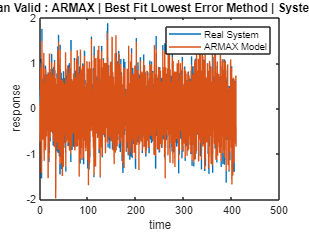

%%
figure(1)
plot(t_val,y2_val,t_val,BestFit_y_hat_prbs)
legend('Real System','ARMAX Model')
title(" PRBS Ident - Guassian Valid : ARMAX | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

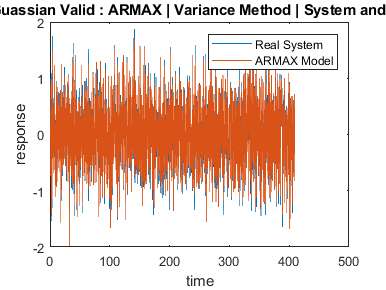


figure(2)
plot(t_val,y2_val,t_val,Var_y_hat_prbs)
legend('Real System','ARMAX Model')
title(" PRBS Ident - Guassian Valid : ARMAX | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

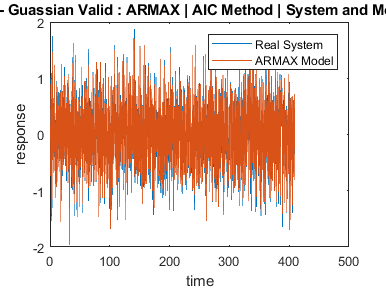


figure(3)
plot(t_val,y2_val,t_val,AIC_y_hat_prbs)
legend('Real System','ARMAX Model')
title(" PRBS Ident - Guassian Valid : ARMAX | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

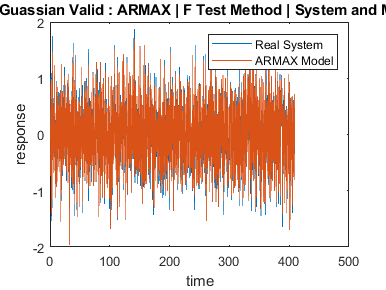


figure(4)
plot(t_val,y2_val,t_val,FTest_y_hat_prbs)
legend('Real System','ARMAX Model')
title(" PRBS Ident - Guassian Valid : ARMAX | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

%%

figure(5)
subplot(4,1,1)
plot(1:N_val-1,armax_BestFit_Ree_prbs(2:end), 1:N_val-1, mean(armax_BestFit_Ree_prbs(2:end))*ones(length(1:N_val-1)))
title(" PRBS Ident - Guassian Valid : ARMAX | Best Fit Lowest Errror Method | Ree_prbs(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_prbs(k)")

subplot(4,1,2)
plot(1:N_val-1,armax_Var_Ree_prbs(2:end), 1:N_val-1, mean(armax_Var_Ree_prbs(2:end))*ones(length(1:N_val-1)))
title(" PRBS Ident - Guassian Valid : ARMAX | Variance Method | Ree_prbs(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_prbs(k)")

subplot(4,1,3)
plot(1:N_val-1,armax_AIC_Ree_prbs(2:end), 1:N_val-1, mean(armax_AIC_Ree_prbs(2:end))*ones(length(1:N_val-1)))
title(" PRBS Ident - Guassian Valid : ARMAX | AIC Method | Ree_prbs(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_prbs(k)")

subplot(4,1,4)
plot(1:N_val-1,armax_FTest_Ree_prbs(2:end), 1:N_val-1, mean(armax_FTest_Ree_prbs(2:end))*ones(length(1:N_val-1)))
title(" PRBS Ident - Guassian Valid : ARMAX | F Test Method | Ree_prbs(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_prbs(k)")


%%

figure(6)
subplot(4,1,1)
plot(1:N_val-1,armax_BestFit_Rue_prbs(2:end), 1:N_val-1, mean(armax_BestFit_Rue_prbs(2:end))*ones(length(1:N_val-1)))
title(" PRBS Ident - Guassian Valid : ARMAX | Best Fit Lowest Errror Method | Rue_prbs(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_prbs(k)")

subplot(4,1,2)
plot(1:N_val-1,armax_Var_Rue_prbs(2:end), 1:N_val-1, mean(armax_Var_Rue_prbs(2:end))*ones(length(1:N_val-1)))
title(" PRBS Ident - Guassian Valid : ARMAX | Variance Method | Rue_prbs(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_prbs(k)")

subplot(4,1,3)
plot(1:N_val-1,armax_AIC_Rue_prbs(2:end), 1:N_val-1, mean(armax_AIC_Rue_prbs(2:end))*ones(length(1:N_val-1)))
title(" PRBS Ident - Guassian Valid : ARMAX | AIC Method | Rue_prbs(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_prbs(k)")

subplot(4,1,4)
plot(1:N_val-1,armax_FTest_Rue_prbs(2:end), 1:N_val-1, mean(armax_FTest_Rue_prbs(2:end))*ones(length(1:N_val-1)))
title(" PRBS Ident - Guassian Valid : ARMAX | F Test Method | Rue_prbs(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_prbs(k)")
